# Modelo de Calcio simultáneo

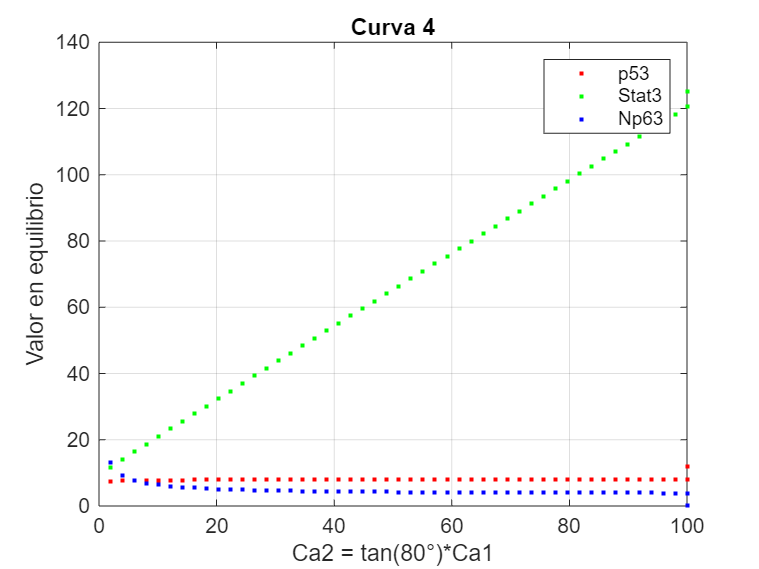

% Preparación del entorno
clear;
clc;
close all;

% Definición simbólica del sistema
syms p53 Stat3 Np63 Ca1 Ca2

% Parámetros
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
Pstat3 = 0.9819;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;
DNp63 = 3.3663;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) - Dp53*p53;
f2 = (Pstat3*Ca1 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63*Ca2;

% Variables simbólicas a resolver
vars = [p53, Stat3, Np63];

% Número de muestras
nSamples = 50;
Ca_vals = linspace(0, 100, nSamples); 

% Inicializar resultados
resultados_id = [];     % Identidad Ca1 = Ca2
resultados_b1 = [];     % Bisectriz 1 
resultados_b2 = [];     % Bisectriz 2
resultados_c3 = [];     % Curva 3
resultados_c4 = [];     % Curva 4

seeds = [0.1 0.1 0.1;1 1 1;5 5 5;10 10 10;20 20 20;30 30 30;40 40 40;50 50 50];

for i = 1:nSamples
    Ca = Ca_vals(i);

    % --- Caso 1: Identidad ---
    val_Ca1 = Ca;
    val_Ca2 = Ca;
    resultados_id = [resultados_id; resolver_sistema(val_Ca1, val_Ca2, f1, f2, f3, vars, seeds, Ca)];

    % --- Caso 2: Ca2 = tan(67.5°)*Ca1 ---
    angulo = 67.5;                    % en grados
    angulo_rad = deg2rad(angulo);     % conversión a radianes
    pendiente = tan(angulo_rad);      % pendiente de la recta
    val_Ca1 = Ca;
    val_Ca2 = pendiente*Ca;
    resultados_b1 = [resultados_b1; resolver_sistema(val_Ca1, val_Ca2, f1, f2, f3, vars, seeds, Ca)];

    % --- Caso 3: Ca2 = tan(22.5°)*Ca1 ---
    angulo = 22.5;                    % en grados
    angulo_rad = deg2rad(angulo);     % conversión a radianes
    pendiente = tan(angulo_rad);      % pendiente de la recta
    val_Ca1 = Ca;
    val_Ca2 = pendiente*Ca;
    resultados_b2 = [resultados_b2; resolver_sistema(val_Ca1, val_Ca2, f1, f2, f3, vars, seeds, Ca)];

    % Curva 3
    angulo = 10;                    
    angulo_rad = deg2rad(angulo);     
    pendiente = tan(angulo_rad);      
    val_Ca1 = Ca;
    val_Ca2 = pendiente*Ca;
    resultados_c3 = [resultados_c3; resolver_sistema(val_Ca1, val_Ca2, f1, f2, f3, vars, seeds, Ca)];

    % Curva 4
    angulo = 80;                    
    angulo_rad = deg2rad(angulo);     
    pendiente = tan(angulo_rad);      
    val_Ca1 = Ca;
    val_Ca2 = pendiente*Ca;
    resultados_c4 = [resultados_c3; resolver_sistema(val_Ca1, val_Ca2, f1, f2, f3, vars, seeds, Ca)];
end

% Curva 4
figure;
plot(resultados_c4(:,1), resultados_c4(:,2), 'r.', 'DisplayName', 'p53'); hold on;
plot(resultados_c4(:,1), resultados_c4(:,3), 'g.', 'DisplayName', 'Stat3');
plot(resultados_c4(:,1), resultados_c4(:,4), 'b.', 'DisplayName', 'Np63');
xlabel('Ca2 = tan(80°)*Ca1');
ylabel('Valor en equilibrio');
title('Curva 4');
legend;
grid on;

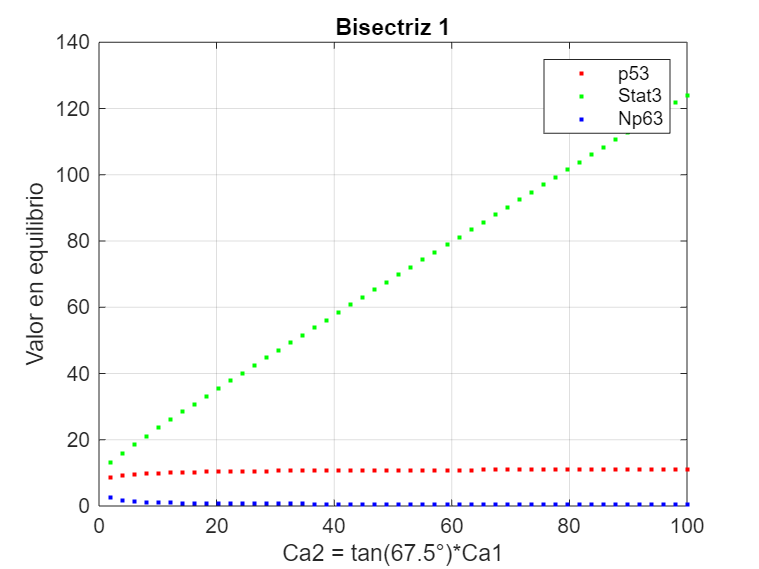


% Bisectriz 1
figure;
plot(resultados_b1(:,1), resultados_b1(:,2), 'r.', 'DisplayName', 'p53'); hold on;
plot(resultados_b1(:,1), resultados_b1(:,3), 'g.', 'DisplayName', 'Stat3');
plot(resultados_b1(:,1), resultados_b1(:,4), 'b.', 'DisplayName', 'Np63');
xlabel('Ca2 = tan(67.5°)*Ca1');
ylabel('Valor en equilibrio');
title('Bisectriz 1');
legend;
grid on;

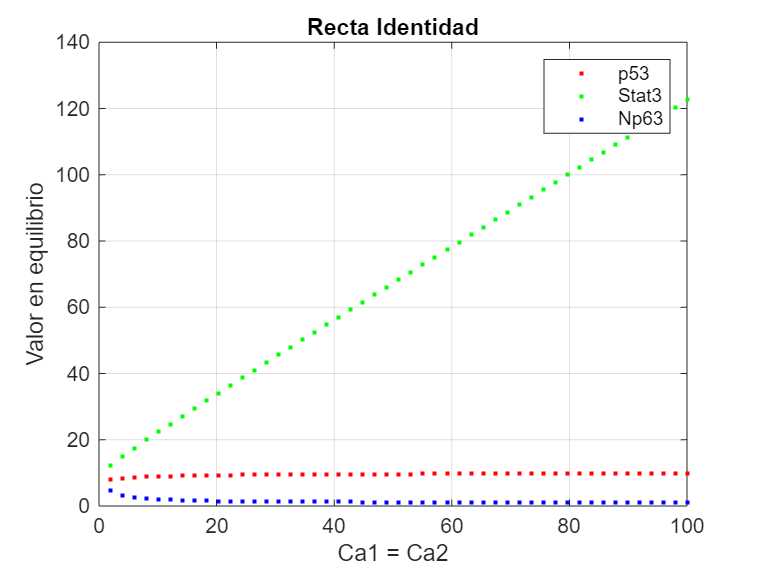


% Identidad
figure;
plot(resultados_id(:,1), resultados_id(:,2), 'r.', 'DisplayName', 'p53'); hold on;
plot(resultados_id(:,1), resultados_id(:,3), 'g.', 'DisplayName', 'Stat3');
plot(resultados_id(:,1), resultados_id(:,4), 'b.', 'DisplayName', 'Np63');
xlabel('Ca1 = Ca2');
ylabel('Valor en equilibrio');
title('Recta Identidad');
legend;
grid on;

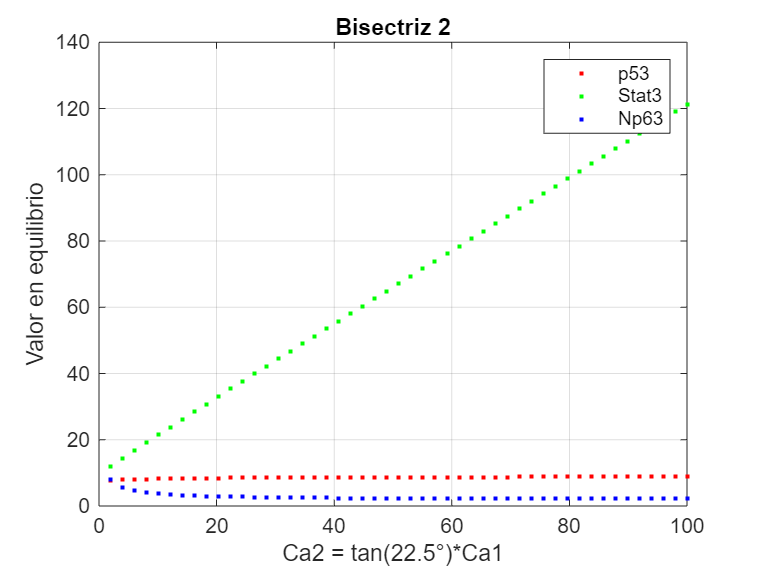


% Bisectriz 2
figure;
plot(resultados_b2(:,1), resultados_b2(:,2), 'r.', 'DisplayName', 'p53'); hold on;
plot(resultados_b2(:,1), resultados_b2(:,3), 'g.', 'DisplayName', 'Stat3');
plot(resultados_b2(:,1), resultados_b2(:,4), 'b.', 'DisplayName', 'Np63');
xlabel('Ca2 = tan(22.5°)*Ca1');
ylabel('Valor en equilibrio');
title('Bisectriz 2');
legend;
grid on;

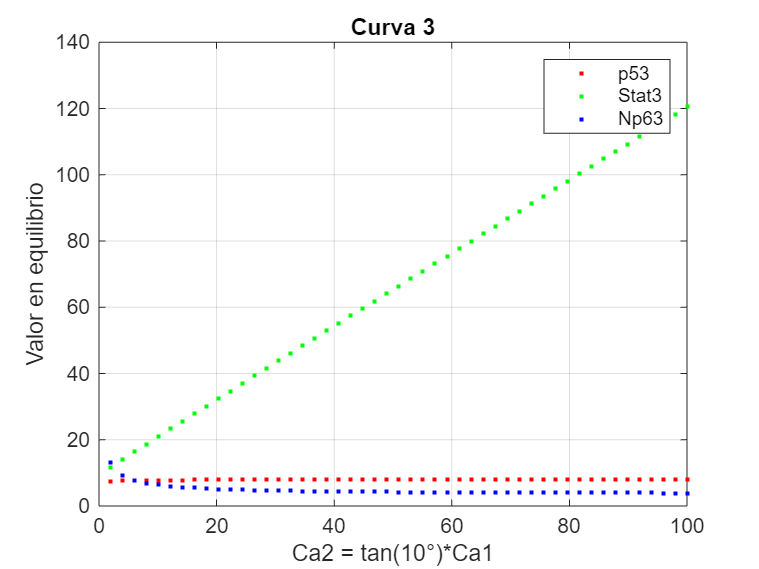


% Curva 3 
figure;
plot(resultados_c3(:,1), resultados_c3(:,2), 'r.', 'DisplayName', 'p53'); hold on;
plot(resultados_c3(:,1), resultados_c3(:,3), 'g.', 'DisplayName', 'Stat3');
plot(resultados_c3(:,1), resultados_c3(:,4), 'b.', 'DisplayName', 'Np63');
xlabel('Ca2 = tan(10°)*Ca1');
ylabel('Valor en equilibrio');
title('Curva 3');
legend;
grid on;

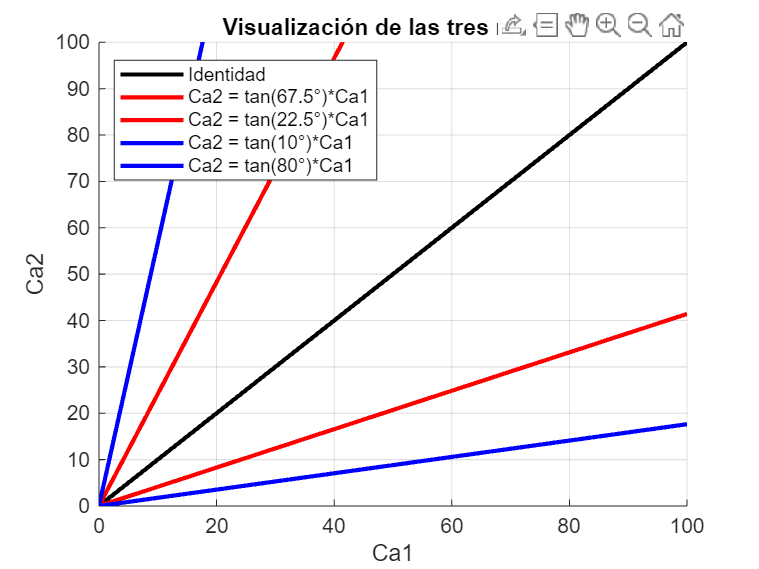


function res = resolver_sistema(Ca1_val, Ca2_val, f1, f2, f3, vars, seeds, Ca_param)
    res = [];
    ecuaciones = [
        subs(f1, {'Ca1', 'Ca2'}, {Ca1_val, Ca2_val}) == 0;
        subs(f2, {'Ca1', 'Ca2'}, {Ca1_val, Ca2_val}) == 0;
        subs(f3, {'Ca1', 'Ca2'}, {Ca1_val, Ca2_val}) == 0;
    ];

    for s = 1:size(seeds, 1)
        try
            sol = vpasolve(ecuaciones, vars, seeds(s,:));
            x1 = double(sol.p53);
            x2 = double(sol.Stat3);
            x3 = double(sol.Np63);
            if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
                res = [res; Ca_param, x1, x2, x3];
            end
        catch
            continue
        end
    end
end

% Gráfico de las tres rectas en el plano (Ca1, Ca2)
figure;
hold on;

% Rango de valores para Ca1 y Ca2
Ca_vals = linspace(0, 100, 100);

% Recta Identidad: Ca1 = Ca2
plot(Ca_vals, Ca_vals, 'k-', 'LineWidth', 2, 'DisplayName', 'Identidad');

% Bisectriz 1: Ca1 = 
angulo = 67.5;                    % en grados
angulo_rad = deg2rad(angulo);     % conversión a radianes
pendiente = tan(angulo_rad);      % pendiente de la recta
Ca1_b1 = Ca_vals;
Ca2_b1 = pendiente*Ca1_b1;
plot(Ca1_b1, Ca2_b1, 'r-', 'LineWidth', 2, 'DisplayName', 'Ca2 = tan(67.5°)*Ca1');

% Bisectriz 2: Ca2 =
angulo = 22.5;                    % en grados
angulo_rad = deg2rad(angulo);     % conversión a radianes
pendiente = tan(angulo_rad);      % pendiente de la recta
Ca1_b2 = Ca_vals;
Ca2_b2 = pendiente*Ca1_b2;
plot(Ca1_b2, Ca2_b2, 'r-', 'LineWidth', 2, 'DisplayName', 'Ca2 = tan(22.5°)*Ca1');

% Curva 3
angulo = 10;                    
angulo_rad = deg2rad(angulo);     
pendiente = tan(angulo_rad);      
Ca1_b2 = Ca_vals;
Ca2_b2 = pendiente*Ca1_b2;
plot(Ca1_b2, Ca2_b2, 'b-', 'LineWidth', 2, 'DisplayName', 'Ca2 = tan(10°)*Ca1');

% Curva 4
angulo = 80;                    
angulo_rad = deg2rad(angulo);     
pendiente = tan(angulo_rad);      
Ca1_b2 = Ca_vals;
Ca2_b2 = pendiente*Ca1_b2;
plot(Ca1_b2, Ca2_b2, 'b-', 'LineWidth', 2, 'DisplayName', 'Ca2 = tan(80°)*Ca1');

xlabel('Ca1');
ylabel('Ca2');
title('Visualización de las tres rectas');
legend('Location', 'best');
axis([0 100 0 100]);
grid on;